# Demo script for vibration controller toolbox

## Install and import required dependencies

- **Toolbox manager** (`tbxmanager`) for MATLAB with `yalmip` and `sedumi`

- **MOSEK** version 9.2 (not necessary but recommended)

install_sedumi_YALMIP =false; % Skip if installed
if install_sedumi_YALMIP
    % Install Toolbox Manager with Sedumi and YALMIP
    install_tbxmanager;     %#ok<UNRCH> 
end

% Path to `%MOSEK_INSTALL_DIR\tools\platform\win64x86\bin\mosek.jar` for windows
% Set to empty if MOSEK is not installed
path_to_mosek = "C:\Program Files\Mosek\9.2\tools\platform\win64x86\bin\mosek.jar";

% Load the dependencies
if ~contains(path, "yalmip")
    tbxmanager restorepath;
end

Toolbox "mpt:3.2.1:all" added to the Matlab path.
Toolbox "mptdoc:3.0.4:all" added to the Matlab path.
Toolbox "cddmex:1.0.1:pcwin64" added to the Matlab path.
Toolbox "fourier:1.0:pcwin64" added to the Matlab path.
Toolbox "glpkmex:1.0:pcwin64" added to the Matlab path.
Toolbox "hysdel:2.0.6:pcwin64" added to the Matlab path.
Toolbox "lcp:1.0.3:pcwin64" added to the Matlab path.
Toolbox "sedumi:1.3:pcwin64" added to the Matlab path.
Toolbox "espresso:1.0:pcwin64" added to the Matlab path.
Toolbox "yalmip:R20210331:all" added to the Matlab path.



% Path to mosek/fusion (if available)
path_to_mosek = strtrim(path_to_mosek);
if (strlength(path_to_mosek) && ~any(strcmp(javaclasspath('-dynamic'), path_to_mosek)))
    javaaddpath(path_to_mosek);
    fprintf("""Mosek"" added to the Matlab path");
end

"Mosek" added to the Matlab path

## Simulation Settings

settings = struct();

settings.save_fits_file = true;    % Save `.fits` files with controller parameters

settings.Fs = 400;           % Sampling Frequency [Hz]
settings.n_photons = 1600;    % No. of photons per timestep for flux noise
settings.solver = "fusion";       % Solver type
settings.readout_noise = false;                 % Detector has readout noise?
settings.tau_lag = 0.0004;      % Communication/Calculation Lag [s]
settings.max_T_sim = 100;    % Max. simulation time [s]

% Extra disturbances
settings.extra_disturbance_type_design = "none";    % Type for controller design 
settings.extra_disturbance_type_sim = "none";       % Type for simulation
settings.extra_disturbance_rms = 5;            % RMS value

% Instrument Disturbance File
settings.instrument_filename = "data\vibrationNRCIMJun2018ForGupta.fits";     % `.fits` file location
settings.instrument_Fs = 800;           % Sampling frequency for instrument noise [Hz]

settings.Fs_sim = settings.Fs;
disp(settings)

                   save_fits_file: 1
                               Fs: 400
                        n_photons: 1600
                           solver: "fusion"
                    readout_noise: 0
                          tau_lag: 4.0000e-04
                        max_T_sim: 100
    extra_disturbance_type_design: "none"
       extra_disturbance_type_sim: "none"
            extra_disturbance_rms: 5
              instrument_filename: "data\vibrationNRCIMJun2018ForGupta.fits"
                    instrument_Fs: 800
                           Fs_sim: 400



## Load Optimised Parameters

if settings.readout_noise
    datafolder = fullfile("data", "readout");
else
    datafolder = fullfile("data", "no_readout");
end

integrator_params = load(fullfile(...
    datafolder, ...
    "optimise_integrator", ...
    "optimised_params.mat"));

datadriven_params = load(fullfile(...
    datafolder, ...
    "optimise_datadriven", ...
    "optimised_params.mat"));

for DoF = ["tip", "tilt"]
    integrator_gain.(DoF) = ...
        integrator_params.get_optimal_gain.(DoF)(settings.Fs, settings.n_photons);
    
    param = cellfun( ...
        @(x) x(settings.Fs, settings.n_photons), ...
        datadriven_params.get_optimal_params.(DoF));
    
    controller_gain.(DoF) = param(1);    
    controller_order.(DoF) = param(2);
    controller_bandwidth.(DoF) = param(3);
    controller_alpha.(DoF) = param(4);
end
fprintf("%s\n", ...
    "|==========================|==========|==========|", ...
    "|   Optimised Parameters   |   Tip    |   Tilt   |", ...
    "|==========================|==========|==========|", ...
    sprintf("| Integrator gain          | %8.4f | %8.4f |", integrator_gain.tip, integrator_gain.tilt), ...
    "|--------------------------|----------|----------|", ...
    sprintf("| Data-driven gain         | %8.4f | %8.4f |", controller_gain.tip, controller_gain.tilt), ...
    sprintf("| Data-driven order        | %8.4f | %8.4f |", controller_order.tip, controller_order.tilt), ...
    sprintf("| Data-driven bandwidth    | %8.4f | %8.4f |", controller_bandwidth.tip, controller_bandwidth.tilt), ...
    sprintf("| Data-driven alpha        | %8.4f | %8.4f |", controller_alpha.tip, controller_alpha.tilt), ...
    "|==========================|==========|==========|");

|==========================|==========|==========|
|   Optimised Parameters   |   Tip    |   Tilt   |
|==========================|==========|==========|
| Integrator gain          |   0.6300 |   0.6300 |
|--------------------------|----------|----------|
| Data-driven gain         |   0.6300 |   0.6300 |
| Data-driven order        |   5.0000 |   5.0000 |
| Data-driven bandwidth    | 100.0000 |  70.0000 |
| Data-driven alpha        | 150.0000 |  80.0000 |
|==========================|==========|==========|


### NFIRAOS & TMT distrubance model

TMT_disturbance = TMT_disturbance_model();
TMT_disturbance.w = logspace(-4, pi, 1000) * settings.instrument_Fs;
TMT_disturbance.Fs_sim = settings.Fs_sim;
TMT_disturbance.add_instrument_disturbance(...
    settings.instrument_filename, ...
    settings.instrument_Fs);

ts = struct();
ts.tip = TMT_disturbance.get_ts("tip", settings.max_T_sim);
ts.tilt = TMT_disturbance.get_ts("tilt", settings.max_T_sim);
ts.noise = utils.get_white_noise(...
    utils.get_flux_noise_rms(settings.n_photons, ...
        "readout_noise", settings.readout_noise), ...
    ts.tip.Time(end), ...
    settings.Fs_sim ...
);
fprintf("NFIRAOS & TMT distrubance model loaded!");

NFIRAOS & TMT distrubance model loaded!

### Extra disturbance

%%% Extra disturbance for controller design 
switch settings.extra_disturbance_type_design
    case "chirp"
        extra_disturbance_design = utils.get_chirp_disturbance( ...
            settings.extra_disturbance_rms, ts.tip.Time(end), settings.Fs_sim ...
            );  
    case "narrowband"
        extra_disturbance_design = utils.get_narrowband_disturbance( ...
            settings.extra_disturbance_rms, 45, 15, ts.tip.Time(end), settings.Fs_sim ...
            );
    otherwise
        % No Disturbance
        time_data = 0:1/settings.Fs_sim:ts.tip.Time(end);
        extra_disturbance_design = timeseries(...
            time_data.' * 0, ...
            time_data, ...
            "Name", "No Extra Disturbance" ...
            );
end

[psd, freq] = pwelch(extra_disturbance_design.Data, [], [], ...
    TMT_disturbance.w / 2 / pi, settings.Fs_sim);
extra_disturbance_design_frd = frd(sqrt(psd), freq * 2 * pi, 1 / settings.Fs_sim);

%%% Extra disturbance for comparision and simulation
switch settings.extra_disturbance_type_sim
    case "chirp"
        extra_disturbance_sim = utils.get_chirp_disturbance( ...
            settings.extra_disturbance_rms, ts.tip.Time(end), settings.Fs_sim ...
            );
    case "narrowband"
        extra_disturbance_sim = utils.get_narrowband_disturbance( ...
            settings.extra_disturbance_rms, 45, 15, ts.tip.Time(end), settings.Fs_sim ...
            );
    otherwise
        % No Disturbance
        time_data = 0:1/settings.Fs_sim:ts.tip.Time(end);
        extra_disturbance_sim = timeseries(...
            time_data.' * 0, ...
            time_data, ...
            "Name", "No Extra Disturbance" ...
            );
end
fprintf("Extra distrubances loaded!");

Extra distrubances loaded!


frd_model = struct();
for DoF = ["tip", "tilt"]
    frd_model.(DoF) = TMT_disturbance.get_frd_model(DoF) + extra_disturbance_design_frd;
end

### Noise

flux_noise_rms = utils.get_flux_noise_rms(settings.n_photons, "readout_noise", settings.readout_noise);

## Controllers

controllers = struct();

### Integrator Controller


$$K(z) = \frac{g}{1 - z^{-1}}$$


where, 

- $g$ is the controller gain

#### Sample Code:

for DoF = ["tip", "tilt"]
    controllers.(DoF).int = VibrationController("int", ...
        "Fs"     , settings.Fs     , ...
        "tau_lag", settings.tau_lag);
    controllers.(DoF).int.update_parameter("gain", integrator_gain.(DoF));
    controllers.(DoF).int.design();
end

### Data-driven Controller

It is represented as an IIR filter of order `n`.


$$
K(z) = \frac{b_0 + b_1\,z^{-1} + \cdots + b_n\,z^{-n}}%
              {1 + a_1\,z^{-1} + \cdots + a_n\,z^{-n}}$$


The parameters ... are found by optimising the following objective,


$$
\min_{K(z)} ~ {\left(
    \left\Vert W_1(z) \, \mathcal{S} \right\Vert_2^2 + \left\Vert W_3(z) \, \mathcal{U} \right\Vert_2^2
\right)}$$


where,

- 
$$W_1(z) = \frac{D(z)}{D(j\omega_{bw}) \, \alpha \, \varsigma}$$


- 
$$W_3(z) = 1$$


- $D(z)$ is the PSD of the disturbance

- $\varsigma$ is the RMS value of the flux noise (measurement noise)

- $\omega_{bw}$ is the desired closed-loop bandwidth

- $\alpha$ is the tradeoff factor between the disturbance rejection and noise minimisation

#### Sample Code:

for DoF = ["tip", "tilt"]
    controllers.(DoF).data = VibrationController("data", ...
        "Fs"     , settings.Fs     , ...
        "tau_lag", settings.tau_lag, ...
        "solver" , settings.solver   ...
    );
    controllers.(DoF).data.set_disturbance_frd(frd_model.(DoF));
    controllers.(DoF).data.set_flux_noise_rms(flux_noise_rms);
    controllers.(DoF).data.update_parameter(...
        "gain"      , controller_gain.(DoF)     , ...
        "order"     , controller_order.(DoF)    , ...
        "bandwidth" , controller_bandwidth.(DoF), ...
        "alpha"     , controller_alpha.(DoF)    );
    controllers.(DoF).data.design(false);
end
fprintf("<<-- Tip -->>"), controllers.tip.data.K

<<-- Tip -->>
ans =
 
  0.6825 z^3 - 1.033 z^2 + 0.5093 z - 0.1369
  ------------------------------------------
      z^3 - 2.402 z^2 + 1.806 z - 0.4033
 
Sample time: 0.0025 seconds
Discrete-time transfer function.



fprintf("<<-- Tilt -->>"), controllers.tilt.data.K

<<-- Tilt -->>
ans =
 
  0.7082 z^3 - 1.143 z^2 + 0.6361 z - 0.1813
  ------------------------------------------
      z^3 - 2.505 z^2 + 2.01 z - 0.5054
 
Sample time: 0.0025 seconds
Discrete-time transfer function.



## Simulations


$$e(z) = \mathcal{S} d(z) + \mathcal{U} n'(z)$$


where,

- 
$$\mathcal{S} = \frac{1}{1 + K(z)\ G(z)}$$


- 
$$\mathcal{U} = \frac{- K(z)}{1 + K(z)\ G(z)}$$


- 
$$G(z) = DM(z)\,WFC(z)\,WFS(z) = \frac{z+1}{2 z^2}$$


- $K(z)$ is the current controller

#### Sample Code:

% Set-up simulators 
simulators = struct();
for DoF = ["tip", "tilt"]
    for type = ["int", "data"]
        simulators.(DoF).(type) = Simulator(settings.Fs, settings.tau_lag);
        simulators.(DoF).(type).set_controller(controllers.(DoF).(type));
        simulators.(DoF).(type).run(ts.(DoF) + extra_disturbance_sim, ts.noise);
    end
end

% Simulation Results
sim_data = utils.deepstructfun(@(x) x.result, simulators);
for DoF = ["tip", "tilt"]
    sim_data.(DoF).raw.disturbance = ts.(DoF).Data + extra_disturbance_sim.data;
    sim_data.(DoF).raw.noise = ts.noise.Data;
    sim_data.(DoF).raw.total = ts.(DoF).Data + ts.noise.Data + extra_disturbance_sim.data;
end

% Calculate PSD data
N = length(ts.tip.Data);
window = hamming(N);
[psd_data, freq_data] = utils.deepstructfun(...
    @(x) pwelch(x, window, [], N, settings.Fs_sim), ...
    sim_data);
freq_data = freq_data.tip.data.disturbance; % All freq_data are same

% RMS values of the residual wavefront
freq_range = [0, settings.Fs_sim/2];
rms_data = utils.deepstructfun(...
    @(x) sqrt(bandpower(x, freq_data, freq_range, 'psd')), ...
    psd_data);

for DoF = ["tip", "tilt"]
    fprintf("%-46s\n", ...
        sprintf("<<-- %s -->> (Controller Order = %d)", DoF, order(controllers.(DoF).data.K)), ...
        sprintf("    Disturbance       => % 12.8f [mas]", rms_data.(DoF).raw.disturbance), ...
        sprintf("      * Integrator    => % 12.8f [mas]", rms_data.(DoF).int.disturbance), ...
        sprintf("      * Data          => % 12.8f [mas]", rms_data.(DoF).data.disturbance), ...
        sprintf("  ------------------------------------------  "), ...
        sprintf("    Flux Noise        => % 12.8f [mas]", rms_data.(DoF).raw.noise), ...
        sprintf("      * Integrator    => % 12.8f [mas]", rms_data.(DoF).int.noise), ...
        sprintf("      * Data          => % 12.8f [mas]", rms_data.(DoF).data.noise), ...
        sprintf("  ------------------------------------------  "), ...
        sprintf("    Total Noise       => % 12.8f [mas]", rms_data.(DoF).raw.total), ...
        sprintf("      * Integrator    => % 12.8f [mas]", rms_data.(DoF).int.total), ...
        sprintf("      * Data          => % 12.8f [mas]", rms_data.(DoF).data.total), ...
        sprintf("  ------------------------------------------  "), ...
        sprintf("    Performance Gain  => % .2f [%%]", ...
            rms_data.(DoF).int.total / rms_data.(DoF).data.total * 100 - 100), ...
        sprintf("==============================================") ...
    );
end

<<-- tip -->> (Controller Order = 3)          
    Disturbance       =>  18.96209190 [mas]   
      * Integrator    =>   0.14534542 [mas]   
      * Data          =>   0.05391409 [mas]   
  ------------------------------------------  
    Flux Noise        =>   0.10018415 [mas]   
      * Integrator    =>   0.06025471 [mas]   
      * Data          =>   0.06358581 [mas]   
  ------------------------------------------  
    Total Noise       =>  18.96173030 [mas]   
      * Integrator    =>   0.15783755 [mas]   
      * Data          =>   0.08345537 [mas]   
  ------------------------------------------  
    Performance Gain  =>  89.13 [%]           
<<-- tilt -->> (Controller Order = 3)         
    Disturbance       =>  17.28170712 [mas]   
      * Integrator    =>   0.13568748 [mas]   
      * Data          =>   0.04540545 [mas]   
  ------------------------------------------  
    Flux Noise        =>   0.10018415 [mas]   
      * Integ

## Bode plot of the residual

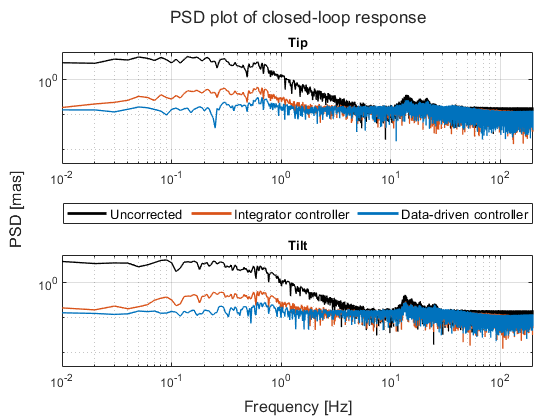

% Effect to consider
type = "total"; % {disturbance, noise, total}

colors = struct();
colors.raw  = "#000000";
colors.int  = "#D95319";
colors.data = "#0072BD";

fig = figure();

t = tiledlayout(2, 1, "TileSpacing", "compact", "Padding", "compact");
xlabel(t, "Frequency [Hz]");
ylabel(t, "PSD [mas]");
title(t, "PSD plot of closed-loop response");

for DoF = ["tip", "tilt"]
    h_plot = struct();
    ax = nexttile();    
    set(ax, 'XScale', 'log', 'YScale', 'log');
    hold on; box on; grid on;
    for controller = ["raw", "int", "data"]
        plot(freq_data, psd_data.(DoF).(controller).(type), ...
            "Color", colors.(controller), ...
            "LineStyle", "-", ...
            "LineWidth", 1 ...
        );
        h_plot.(controller) = plot([-inf, -inf], [0, 1], ...
            "Color", colors.(controller), ...
            "LineStyle", "-", ...
            "LineWidth", 2 ...
        );
    end
    xlim([1e-2, settings.Fs_sim / 2]);
    ylim([10^-12, 10^4]);
    title(sprintf("%s", ...
        regexprep(lower(DoF), "(^|\.)\s*.", "${upper($0)}")));
end

legend([h_plot.raw, h_plot.int, h_plot.data], ...
    "Uncorrected", ...
    "Integrator controller", ...
    "Data-driven controller", ...
    "FontSize", 10, ...
    "Orientation", "horizontal", ...
    "Location", "northoutside");

## Save `.fits` file with controller parameters

if settings.save_fits_file
    for DoF = ["tip", "tilt"]
        filename = "parameters-" + DoF;
        controllers.(DoF).data.save_to_fits(filename);
    end
end